# German Stocks - Multivariate Statistics

## 1.

Load the table stored in the file `daxReturns.mat`.

load daxReturns

## 2.

Extract the stock returns (variables 2 to 31) into a `double` variable.

stocks = daxReturns{:,2:end}

stocks =     0.0014   -0.0209   -0.0193    0.0163   -0.0127   -0.0012    0.0207   -0.0143   -0.0106   -0.0103   -0.0135   -0.0113   -0.0103   -0.0022   -0.0130   -0.0049   -0.0119    0.0118    0.0018   -0.0333   -0.0124    0.0039    0.0059    0.0063   -0.0121    0.0087   -0.0116   -0.0102   -0.0186   -0.0165
    0.0008    0.0206    0.0107    0.0267    0.0075    0.0128    0.0143    0.0157    0.0177    0.0612    0.0081   -0.0052    0.0126    0.0321    0.0166    0.0043    0.0075    0.0213    0.0217    0.0177    0.0166    0.0215   -0.0091    0.0153    0.0106    0.0179    0.0195    0.0102    0.0311    0.0057
    0.0106    0.0046    0.0106    0.0291    0.0092    0.0045    0.0114   -0.0051    0.0138   -0.0097    0.0091    0.0057    0.0024    0.0093    0.0100    0.0030    0.0044    0.0133   -0.0018    0.0339    0.0133    0.0112    0.0176    0.0081    0.0018    0.0033   -0.0805    0.0083    0.0209    0.0020
    0.0080    0.0030    0.0044   -0.0044    0.0133    0.0080   -0.0007    0.0051    0.00

## 3.

Perform a principal component analysis (PCA) on the stock returns and ask for at least two outputs.

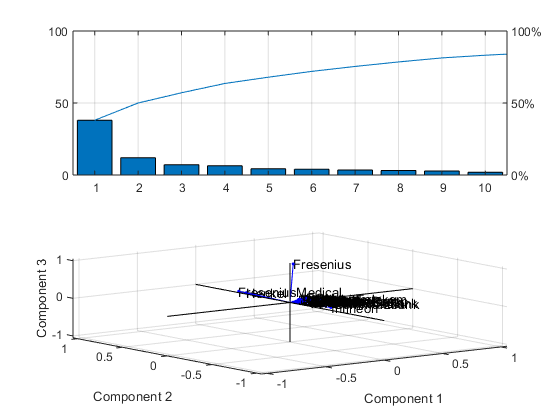

[coeff,scores,~,~,variance] = pca(stocks);

figure
subplot(2,1,1)
pareto(variance)
grid('on')
subplot(2,1,2)
biplot(coeff(:,1:3), 'VarLabels', daxReturns.Properties.VariableNames(2:end))

## 4.

Choose one original return series.  Approximate this series by fitting the first 10 principal components. **Hint** No regression necessary; multiply the PCA scores with the corresponding PCA coefficients.

stockIdx = randi(30,1);
PCAfit = scores(:,1:10) * coeff(stockIdx,1:10)'

PCAfit =    -0.0047
    0.0150
    0.0068
    0.0023
   -0.0021
   -0.0052
   -0.0091
    0.0016
   -0.0052
   -0.0047


## 5.

Visually compare the returns by plotting the original returns and the approximation (from step 4) on the same axis against the dates.

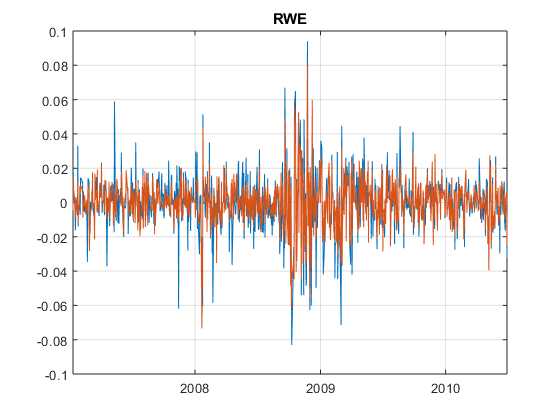

dates = datetime(daxReturns.Properties.RowNames,'InputFormat','dd-MMM-yyyy');

figure
plot(dates, [stocks(:,stockIdx), PCAfit]);
title(daxReturns.Properties.VariableNames{1+stockIdx})
datetick
xlim([dates(1),dates(end)])
grid('on')